## Get CTCF data

TF_of_interest = 'CTCF';
load_name = strcat(TF_of_interest, '_chr1_2_data');
load(load_name)

% remove strand column
Arr(:, 177) = [];
col1 = Arr(:, 1);
Arr = Arr(col1~=0, :);
Arr_roll = [Arr(:, [45:66]) Arr(:, [177:178])]

Arr_roll =    -1.8700    4.3600   -2.0000    3.0800   -0.7300    3.4900   -1.9800   -1.6100    2.8900   -2.7600   -0.6600    2.7600   -2.9200   -1.6400   -2.9000    2.7700   -1.4300   -1.5800    3.4600   -1.9800   -2.1200    3.9300  -13.0000    1.0000
   -1.0600   -1.5000    3.9300   -2.1200   -1.9800    3.4600   -1.5800   -1.4300    2.7700   -2.9000   -1.6400   -2.9200    2.7600   -0.6600   -2.7600    2.8900   -1.6100   -1.9800    3.4900   -0.7300    3.0800   -2.0000  -10.0000    1.0000
   -2.8400   -3.5300    4.1200   -2.2700   -1.9300    4.7500   -1.6500   -3.7100   -2.4100   -3.0300   -1.0600   -1.5000    3.9300   -2.1200   -1.9800    3.4600   -1.5800   -1.4300    2.7700   -2.9000   -1.6400   -2.9200  -11.0000    1.0000
   -3.1600   -3.5500    5.4800    0.2000   -3.1800   -2.5800   -2.3200    2.8700   -1.6900   -1.7900   -2.2100   -2.1700   -1.1900    5.5600   -3.5300   -3.1500   -2.9100   -1.9700   -1.8700    3.9600   -4.7100   -2.2800  -14.0000         0
   -2.3300   -1.2700   -1

### Take only one shape aspect

lastColumn = Arr(:,178);
positive_data = Arr(lastColumn==1, :);
negative_data = Arr(lastColumn==0, :);
x_data_positive = positive_data(:, [45:66]);
x_data_avg = mean(x_data_positive)

x_data_avg =    -1.0616   -0.6851   -1.1125   -0.9554   -0.5592   -1.3888   -0.9387   -1.0312   -1.1678   -0.8428   -1.2576   -0.8461   -1.1331   -1.1948   -0.5049   -1.0780   -0.3634   -0.5322   -1.0476   -0.6562   -1.0971   -1.1892


x_data_negative = negative_data(:, [45:66]);
x_data_avg_negative = mean(x_data_negative)

x_data_avg_negative =    -1.1646   -0.5026   -1.2342   -0.6210   -1.1966   -1.3656   -1.1863   -1.0452   -1.2123   -1.1314   -0.7454   -0.7771   -1.1275   -0.9782   -0.7157   -1.1898   -0.6025   -0.5694   -0.9733   -0.7626   -0.9716   -1.1959


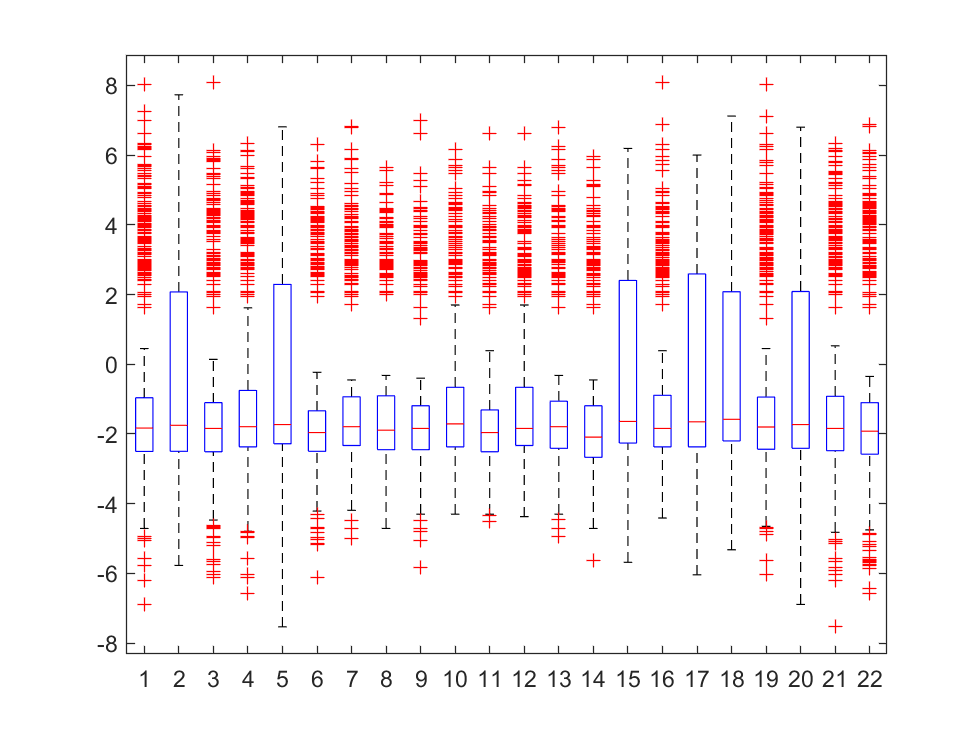


figure;
boxplot(x_data_positive)

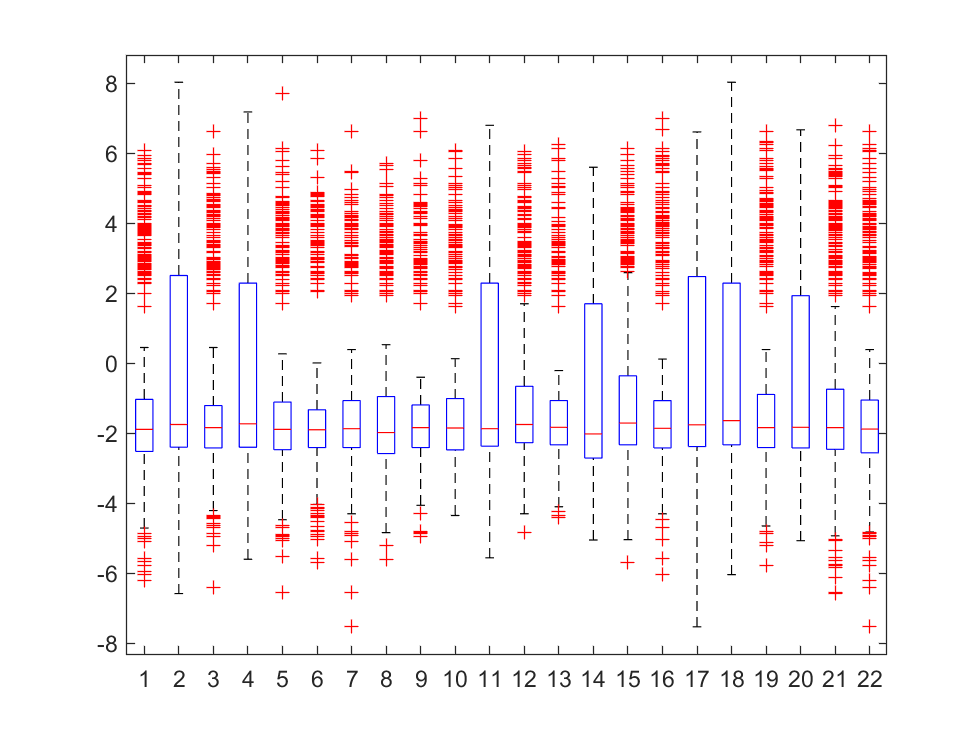

figure;
boxplot(x_data_negative)


avgs_CTCF = [x_data_avg' x_data_avg_negative']

avgs_CTCF =    -1.0616   -1.1646
   -0.6851   -0.5026
   -1.1125   -1.2342
   -0.9554   -0.6210
   -0.5592   -1.1966
   -1.3888   -1.3656
   -0.9387   -1.1863
   -1.0312   -1.0452
   -1.1678   -1.2123
   -0.8428   -1.1314


% figure;
% stackedplot(avgs_CTCF)

x_data_positive = positive_data(:, 46);
x_data_avg = mean(x_data_positive)

x_data_avg = -0.6851

x_data_negative = negative_data(:, 46);
x_data_avg_negative = mean(x_data_negative)

x_data_avg_negative = -0.5026

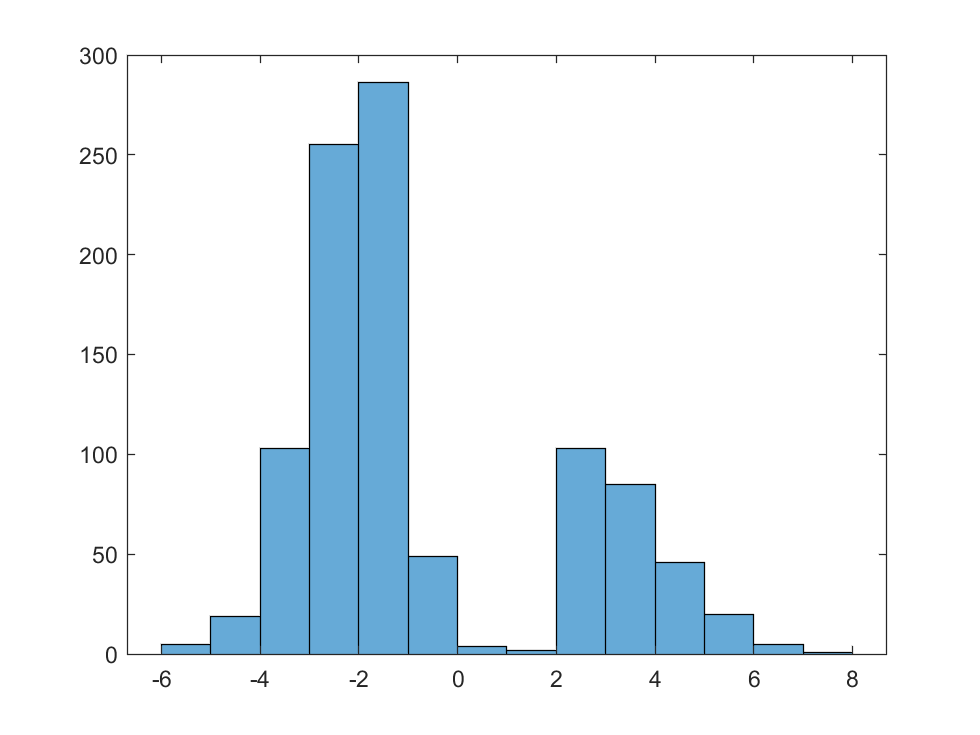

figure;
histogram(x_data_positive)

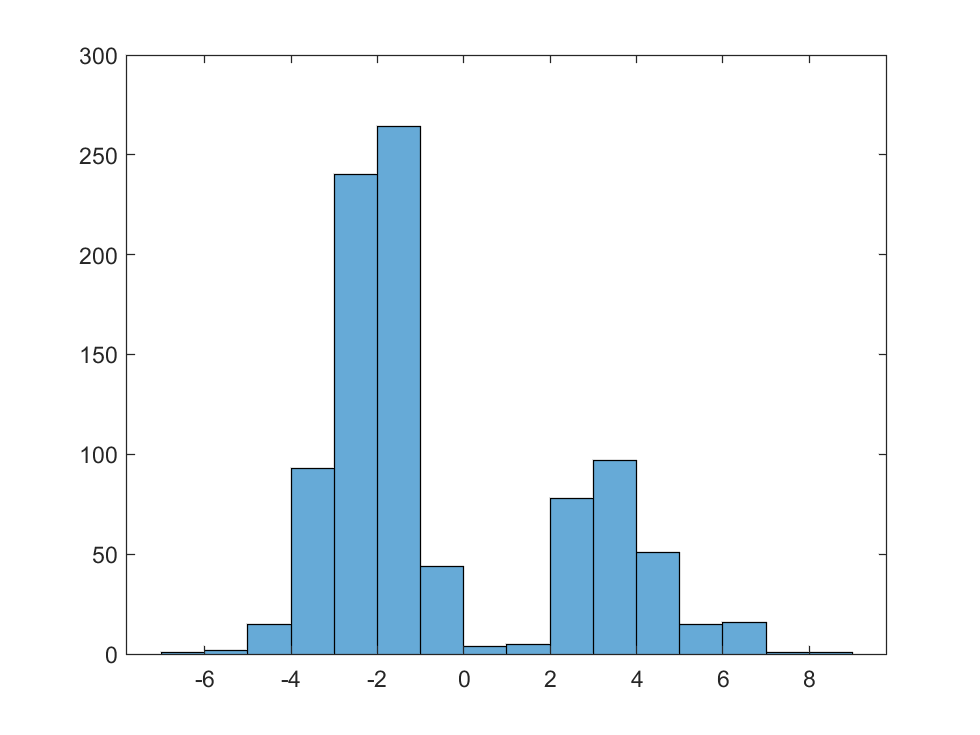

figure;
histogram(x_data_negative)

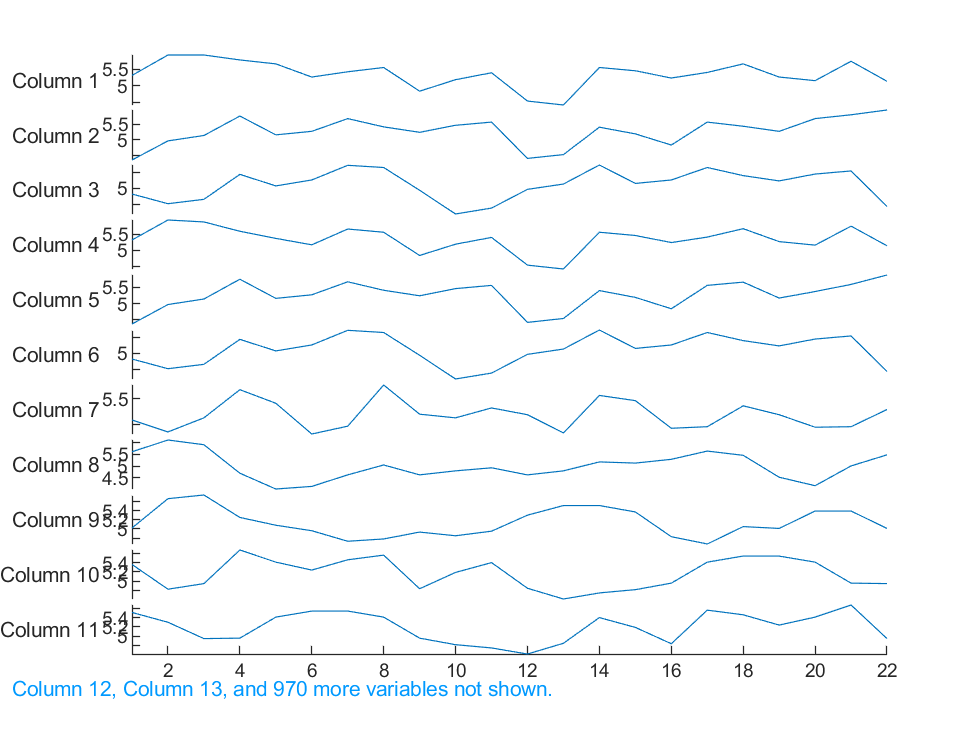


figure;
% stackedplot(x_data_positive')

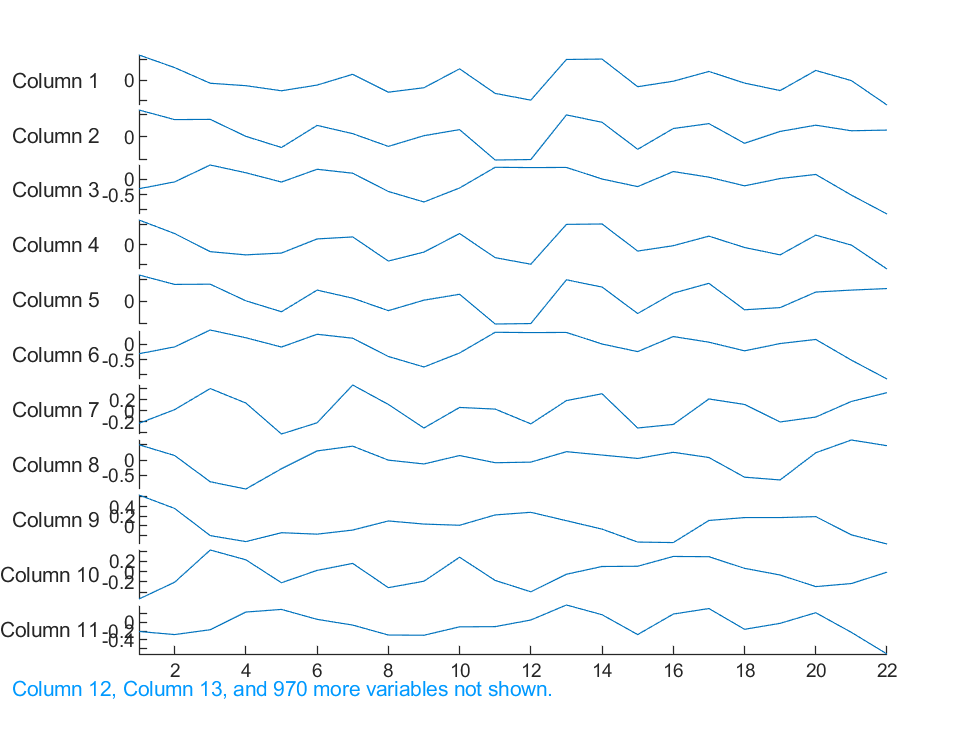

% stackedplot(x_data_negative)
x_data_positive_deriv = gradient(x_data_positive);
x_data_positive_deriv = x_data_positive_deriv';
% stackedplot(x_data_positive_deriv)


x_data_negative_deriv = gradient(x_data_negative);
x_data_negative_deriv = x_data_negative_deriv';

x_data_deriv = gradient(Arr(:, [1:22]));
Arr_MGW_deriv = [x_data_deriv Arr(:, [177:178])];

## Get ELF1 data

elf_data = load("ELF1_data.mat");
elf_arr = [elf_data.x_data elf_data.y_data];
col1 = elf_arr(:, 1);
elf_arr = elf_arr(col1~=0, :)

elf_arr =     4.7300    4.5300    4.5100    4.9000    4.9500    5.3000    5.5100    5.4200    5.5600    5.1900    5.0900    5.0800    4.9600    4.9500    5.1900    5.3900    5.0900    4.6300    4.2700    3.8400    4.8900    5.2300   -6.7500   -3.1100   -7.3400   -5.2800   -2.5600   -2.7500   -4.2500   -4.2700   -6.9000   -8.4900   -7.3800   -3.6300   -2.8900   -2.7300   -3.2600   -3.1900   -5.3600  -10.0900  -12.0900  -11.7600   -9.5900   -3.6800   -0.9200   -1.8300    2.5100   -1.1900    4.5700   -1.4300
    4.2100    4.4300    4.0500    3.3800    3.3800    4.7600    5.2100    4.9700    5.2400    5.6500    5.9100    4.9400    4.4500    4.7000    5.1900    5.3900    5.0900    4.6300    4.7400    4.4300    4.6200    5.0600  -10.3900  -13.1500  -14.4700  -16.5100  -16.5100  -13.7900  -12.0300  -10.1700  -11.6900  -10.2200   -7.0700   -7.9600   -5.3300   -3.5300   -3.2600   -3.1900   -5.3600  -10.0900  -12.7600  -13.1500  -10.0400   -3.3600   -5.0700   -3.9000   -2.3800    6.1700   -2.400

% remove strand column
elf_arr(:, 89) = [];
elf_MGW = [elf_arr(:, [45:66]) elf_arr(:, [89:90])];
x_data_elf = elf_MGW(:, [1:22])'

x_data_elf =    -0.9200   -5.0700   -1.2400   -1.5800   -2.3700   -1.7000   -1.9700    3.9200   -2.1600   -0.9200   -1.3600   -1.4400    2.0800   -3.1500    3.4000   -1.3200    4.5700   -3.6300   -0.6800   -1.0900   -1.8300   -0.6100   -3.2900   -0.5600   -2.3700   -1.6400   -0.8800    2.2300    3.8200   -0.6600   -0.9400    1.3100    3.2000   -1.3900   -2.2200    3.8700   -1.7500   -0.8500   -1.2600   -1.2500   -1.8500   -1.0000    5.5600   -5.1500   -2.2000   -1.4300   -0.6500   -3.0600   -2.1000    5.1500
   -1.8300   -3.9000   -2.1300   -1.3300   -1.7500   -0.9300   -2.2100   -5.5600   -2.3700   -1.8300   -1.2900   -2.8400   -1.3100   -2.9100   -2.4800    2.7300   -1.3500   -3.0000   -1.7000   -3.4300   -1.0900    1.6200   -1.7100   -1.9300   -2.6200   -2.9000    4.0800   -0.6400   -3.9500    2.9400    4.6000   -1.0400   -0.7000   -2.2700    4.0300   -1.0200   -2.3700   -1.6700   -1.8300   -1.3500    2.5800   -2.2000   -1.1900   -3.4600   -1.1500   -2.0400   -3.8100    5.8200   -2.

elf_avg = mean(elf_MGW(:, [1:22]), 1)

elf_avg =    -0.5928   -0.8931   -0.9118   -1.2817   -0.8856   -0.5250   -0.5062   -1.0552   -1.8771   -1.8200   -2.0498   -0.3599   -1.6985   -1.0689   -2.3347   -1.0315   -1.5683   -0.3523   -0.6716   -1.0653   -0.7913   -0.8270


### Take only MGW

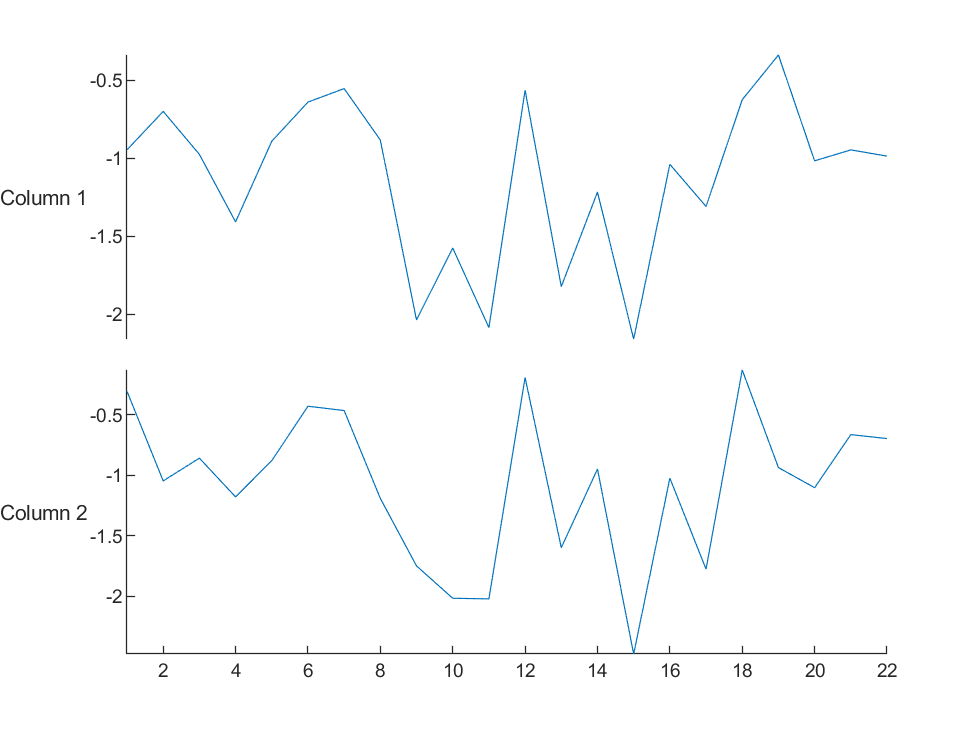

elf_lastColumn = elf_MGW(:,24);
elf_positive_data_MGW = elf_MGW(elf_lastColumn==1, :);
elf_negative_data_MGW = elf_MGW(elf_lastColumn==0, :);

x_data_positive_elf = elf_positive_data_MGW(:, [1:22]);
x_data_avg_elf = mean(x_data_positive_elf);

avgs = [x_data_avg_elf' x_data_avg'];
% figure;
% stackedplot(avgs)
x_data_neg_elf = elf_negative_data_MGW(:, [1:22]);
x_data_avg_elf_neg = mean(x_data_neg_elf);

avgs_neg = [x_data_avg_elf_neg' x_data_avg_elf'];
figure;
stackedplot(avgs_neg)

most_common_positive = -1.5000

mean_positive = -1.0616

std_positive = 2.4988

most_common_negative = -1.5000

mean_negative = -1.1646

std_negative = 2.4217

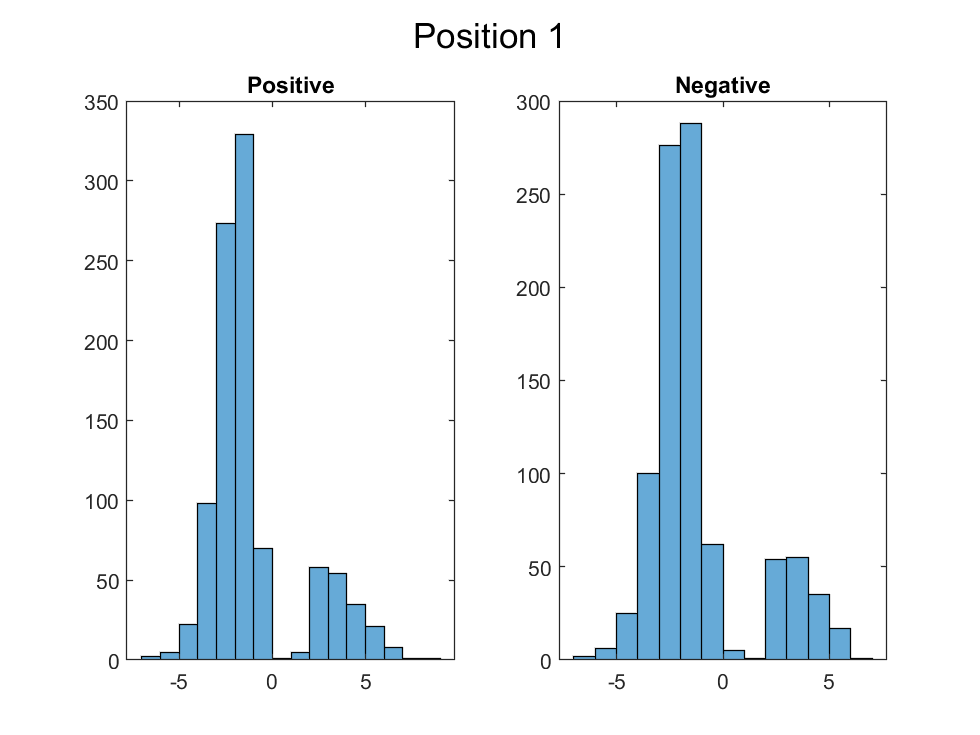

most_common_positive = -1.5000

mean_positive = -0.6851

std_positive = 2.6995

most_common_negative = -1.5000

mean_negative = -0.5026

std_negative = 2.8291

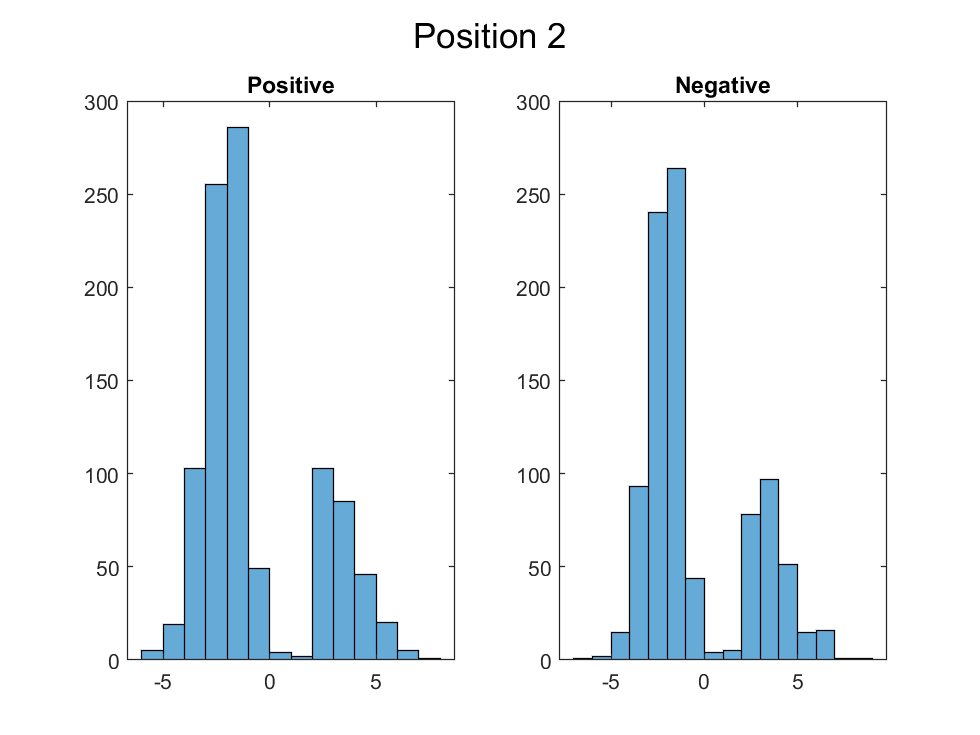

most_common_positive = -1.5000

mean_positive = -1.1125

std_positive = 2.4459

most_common_negative = -1.5000

mean_negative = -1.2342

std_negative = 2.1836

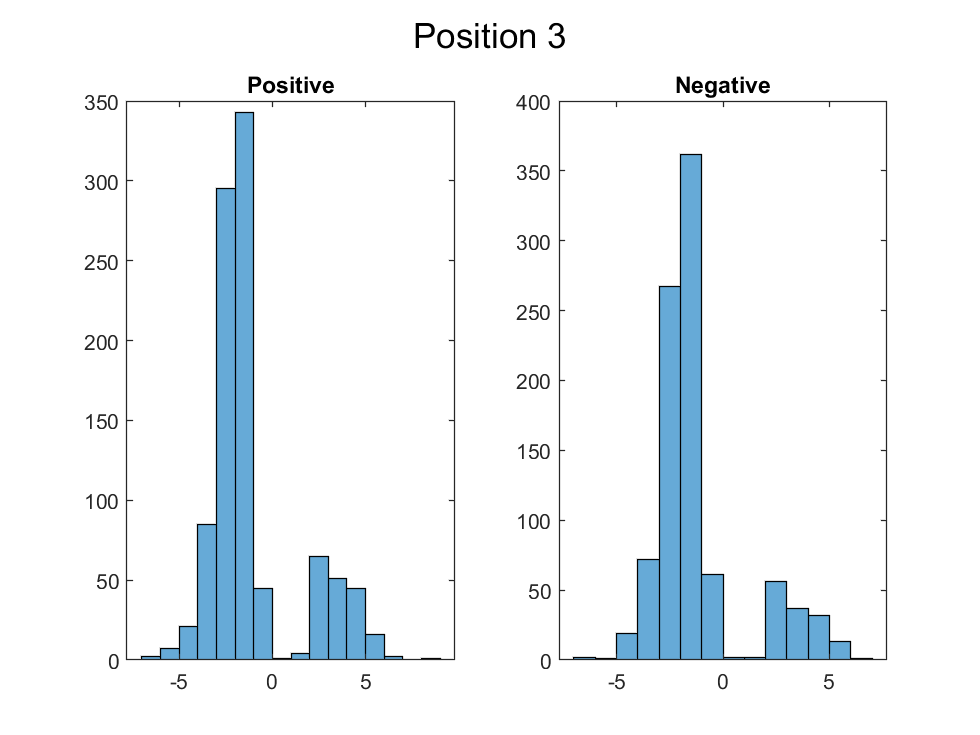

most_common_positive = -1.5000

mean_positive = -0.9554

std_positive = 2.4342

most_common_negative = -1.5000

mean_negative = -0.6210

std_negative = 2.6670

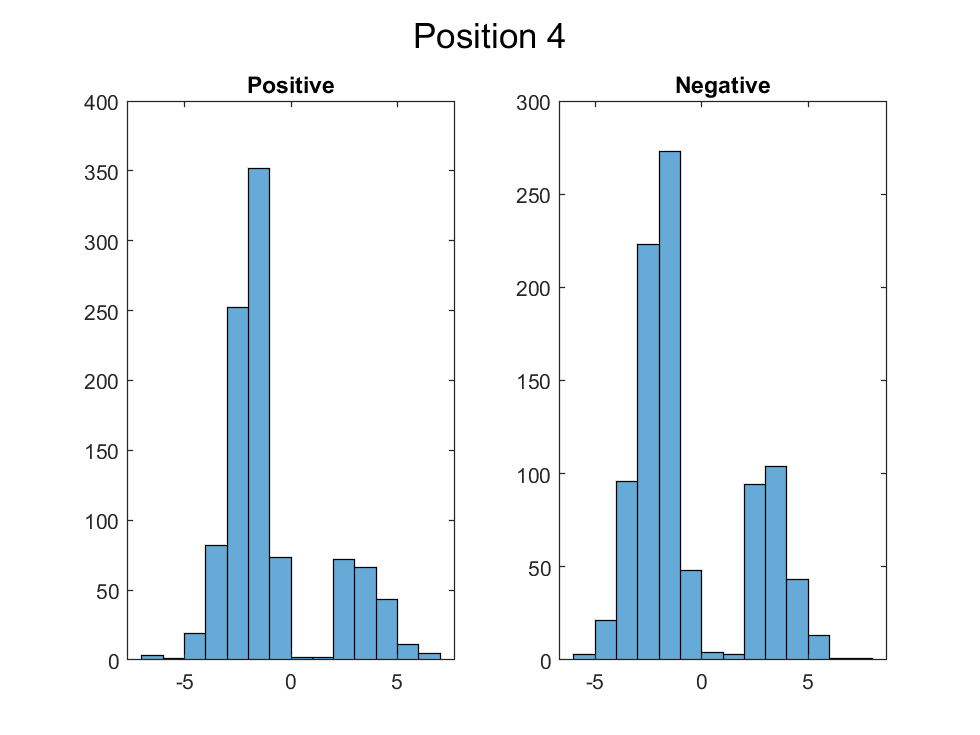

most_common_positive = -1.5000

mean_positive = -0.5592

std_positive = 2.6437

most_common_negative = -1.5000

mean_negative = -1.1966

std_negative = 2.3032

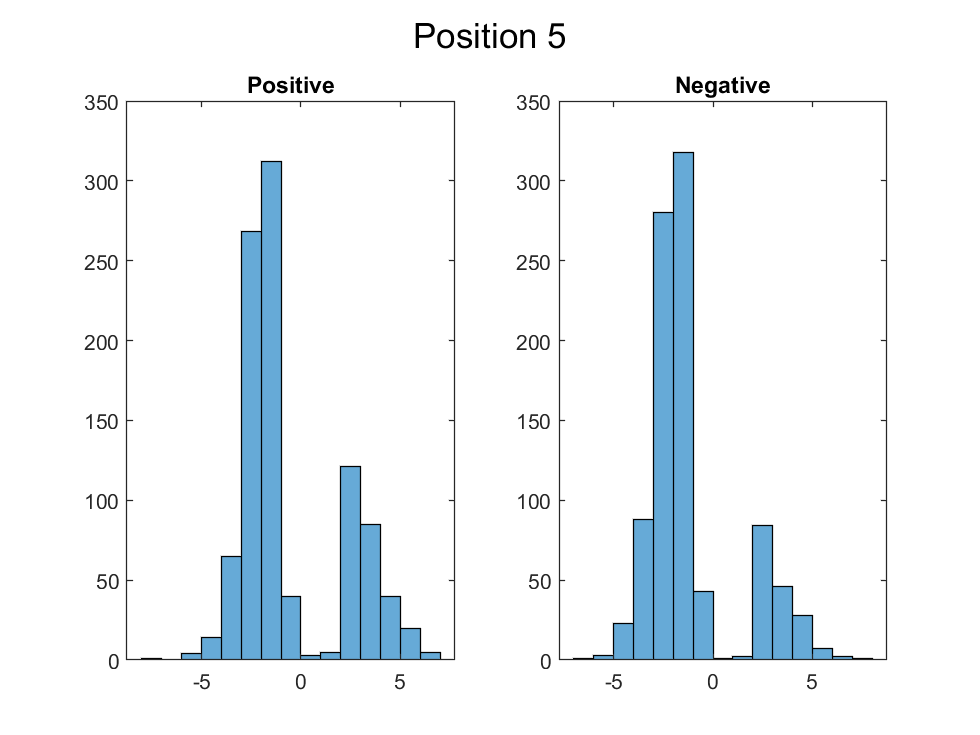

most_common_positive = -1.7500

mean_positive = -1.3888

std_positive = 2.1035

most_common_negative = -1.5000

mean_negative = -1.3656

std_negative = 2.1183

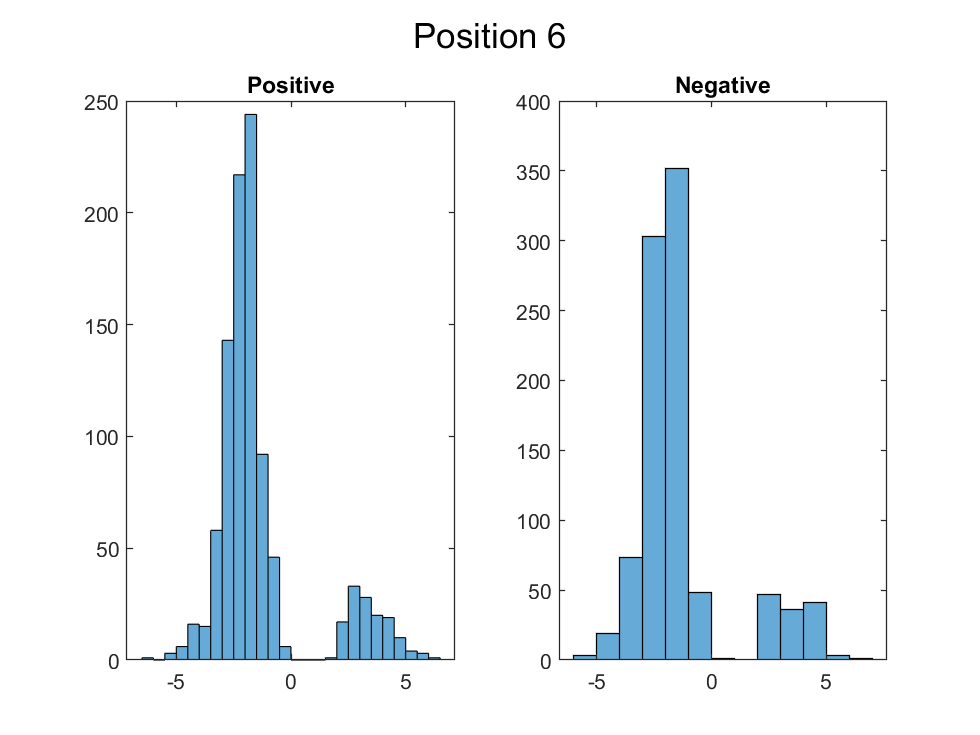

most_common_positive = -1.5000

mean_positive = -0.9387

std_positive = 2.2776

most_common_negative = -1.5000

mean_negative = -1.1863

std_negative = 2.1187

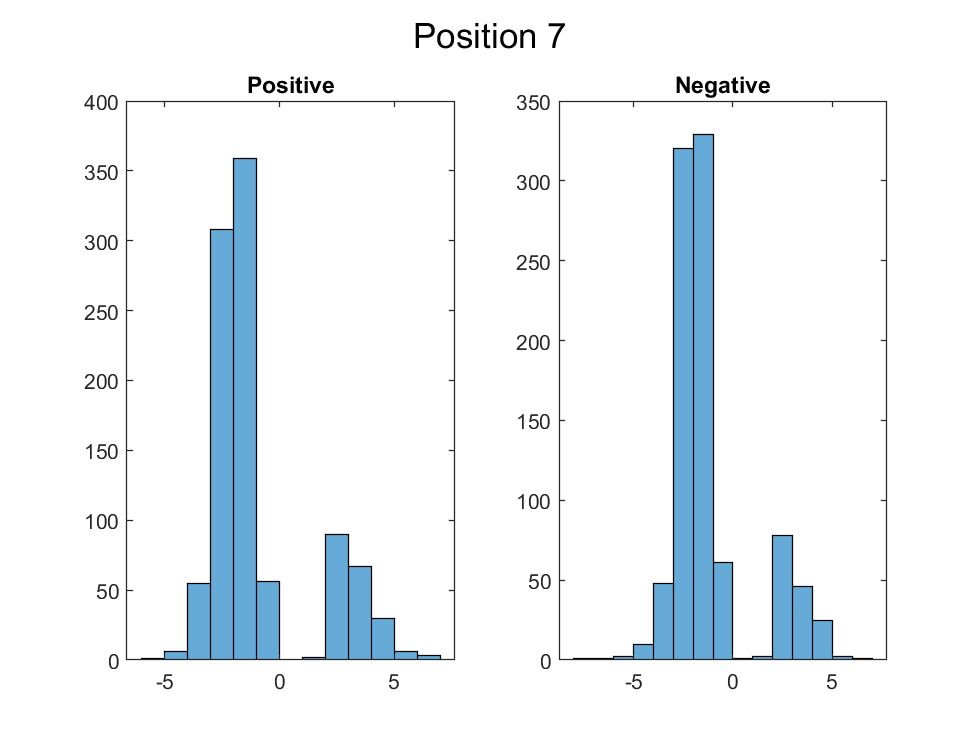

most_common_positive = -2.5000

mean_positive = -1.0312

std_positive = 2.2955

most_common_negative = -2.5000

mean_negative = -1.0452

std_negative = 2.4093

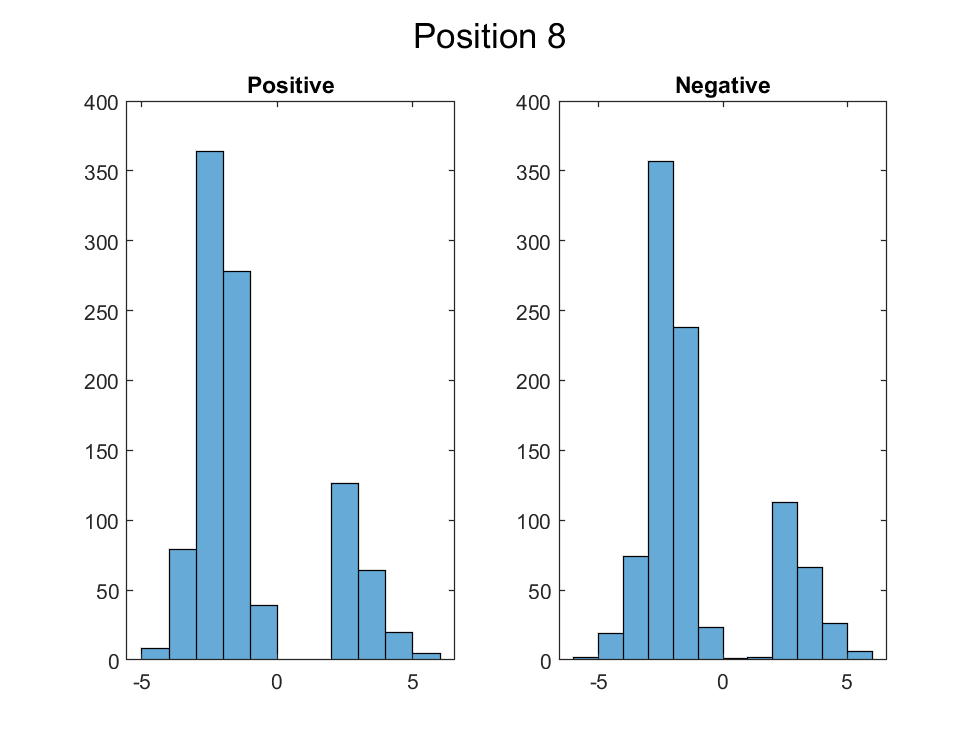

most_common_positive = -1.5000

mean_positive = -1.1678

std_positive = 2.1708

most_common_negative = -1.7500

mean_negative = -1.2123

std_negative = 2.0842

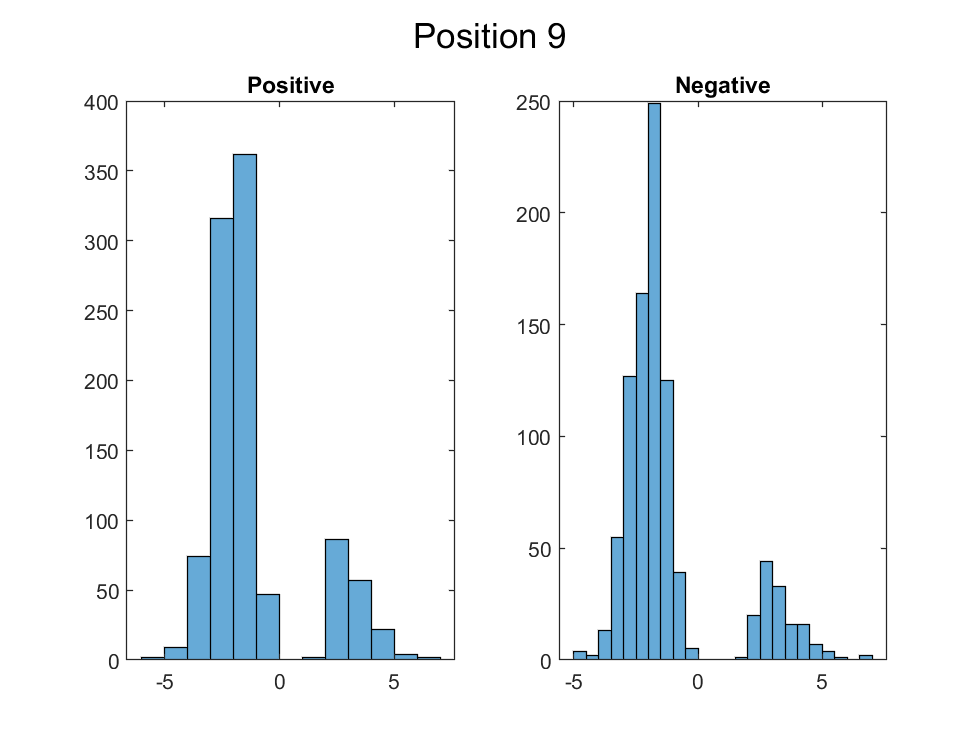

most_common_positive = -1.5000

mean_positive = -0.8428

std_positive = 2.3386

most_common_negative = -1.5000

mean_negative = -1.1314

std_negative = 2.2304

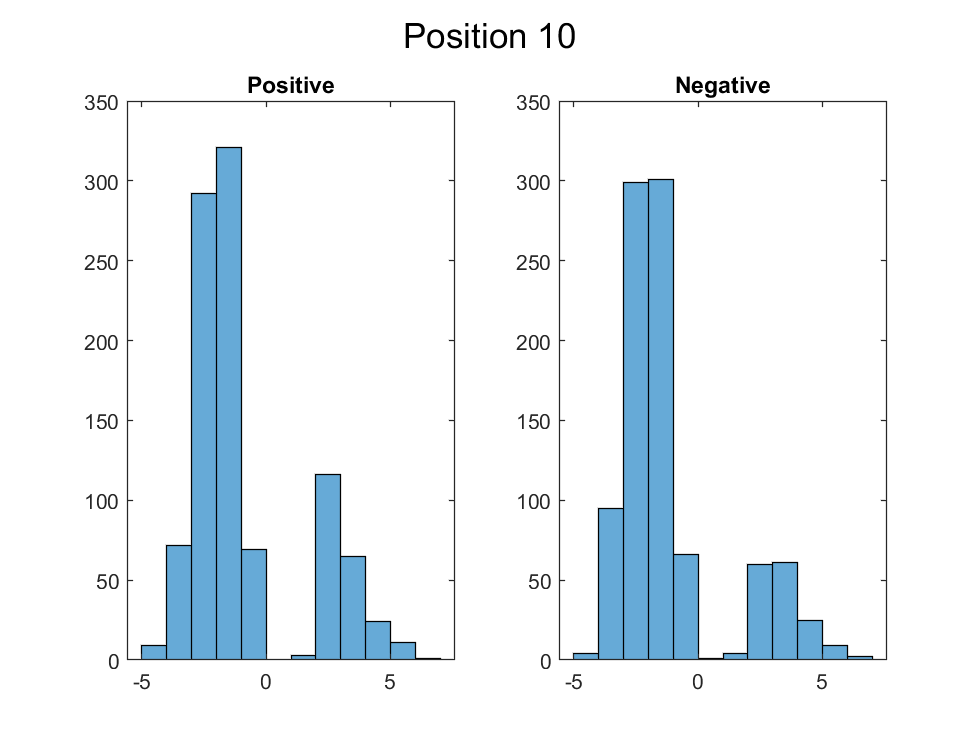

most_common_positive = -1.7500

mean_positive = -1.2576

std_positive = 2.1287

most_common_negative = -2.5000

mean_negative = -0.7454

std_negative = 2.4930

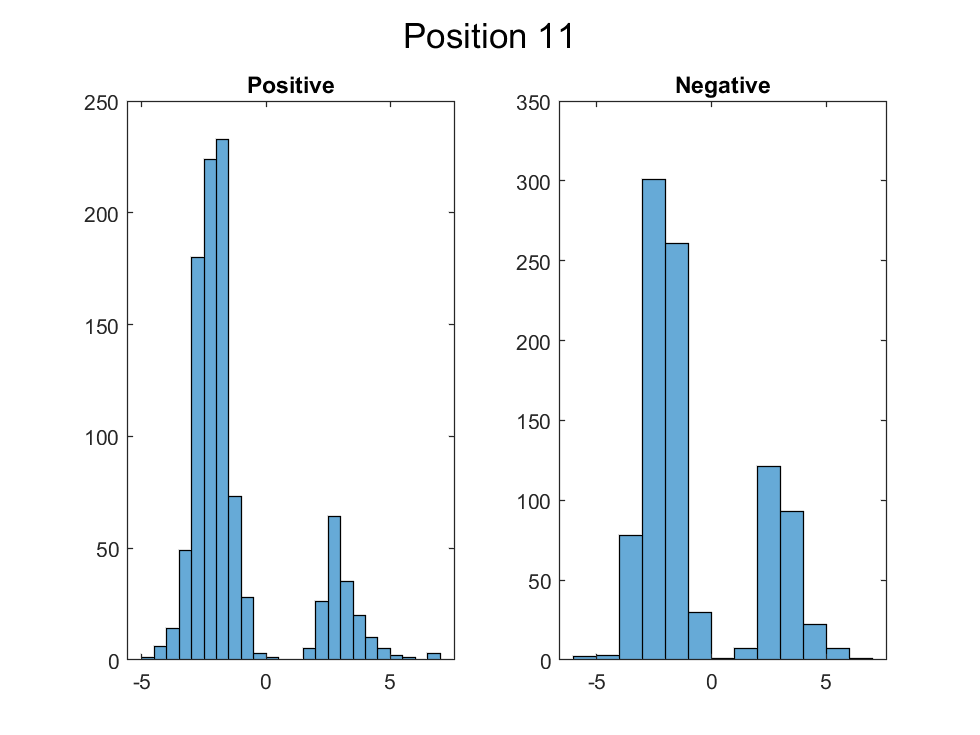

most_common_positive = -2.5000

mean_positive = -0.8461

std_positive = 2.3136

most_common_negative = -2.5000

mean_negative = -0.7771

std_negative = 2.3625

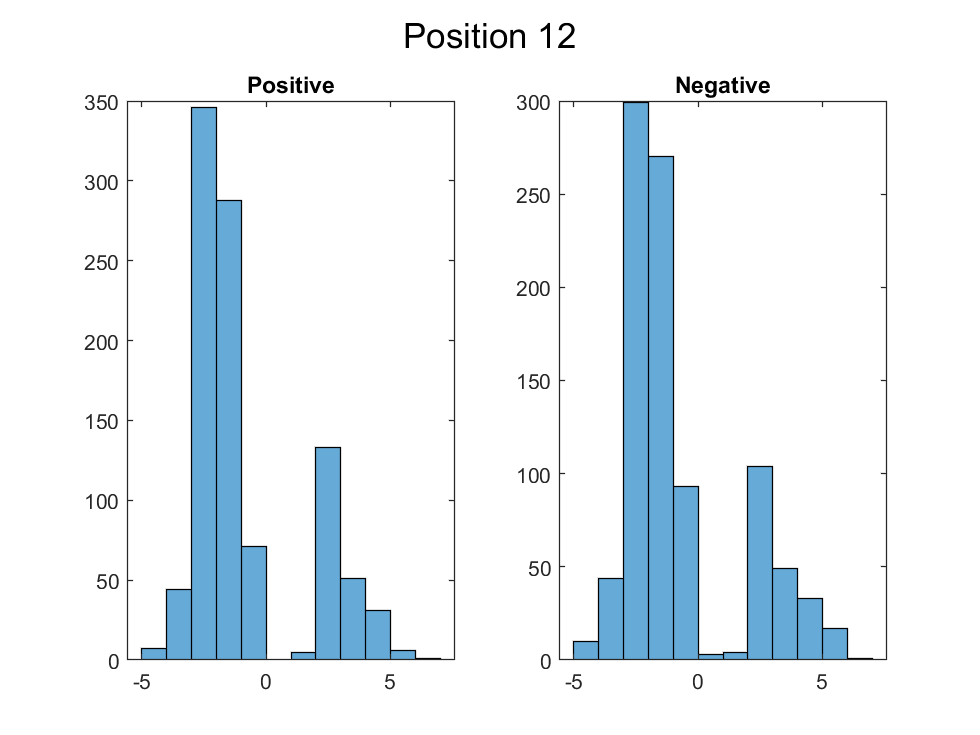

most_common_positive = -1.7500

mean_positive = -1.1331

std_positive = 2.1197

most_common_negative = -1.7500

mean_negative = -1.1275

std_negative = 2.0782

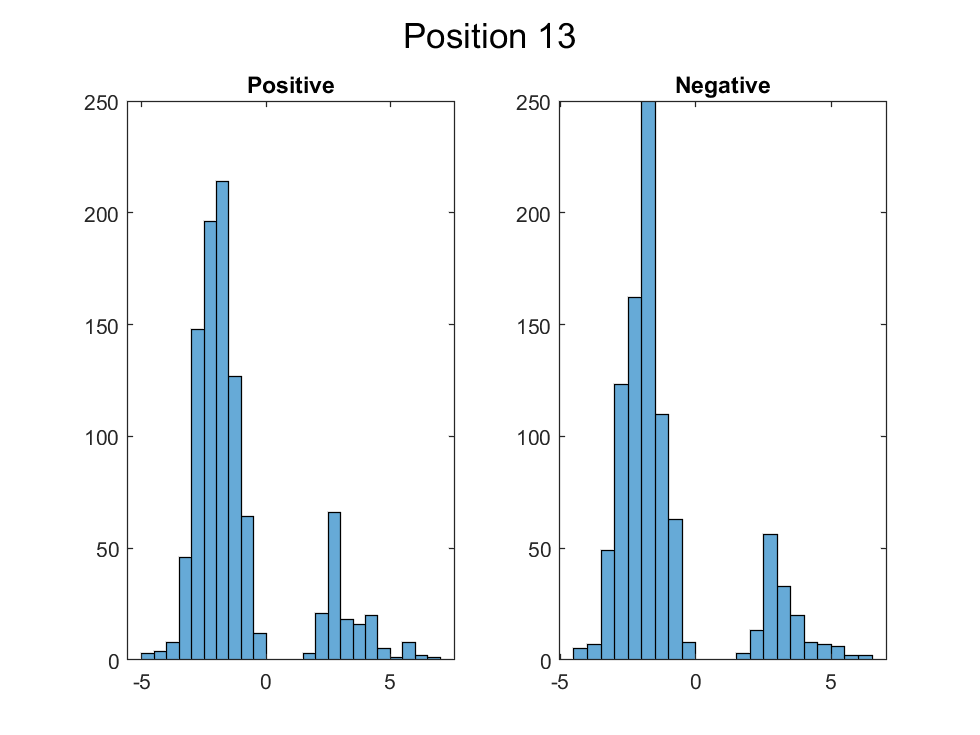

most_common_positive = -2.5000

mean_positive = -1.1948

std_positive = 2.3011

most_common_negative = -2.5000

mean_negative = -0.9782

std_negative = 2.4930

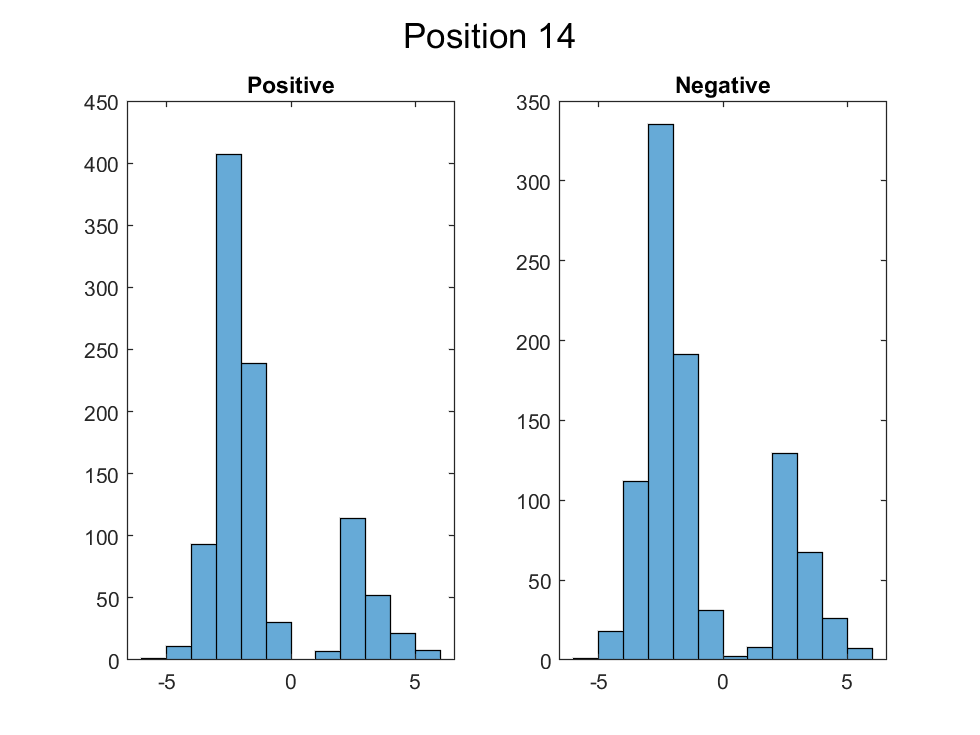

most_common_positive = -1.5000

mean_positive = -0.5049

std_positive = 2.5119

most_common_negative = -1.5000

mean_negative = -0.7157

std_negative = 2.5006

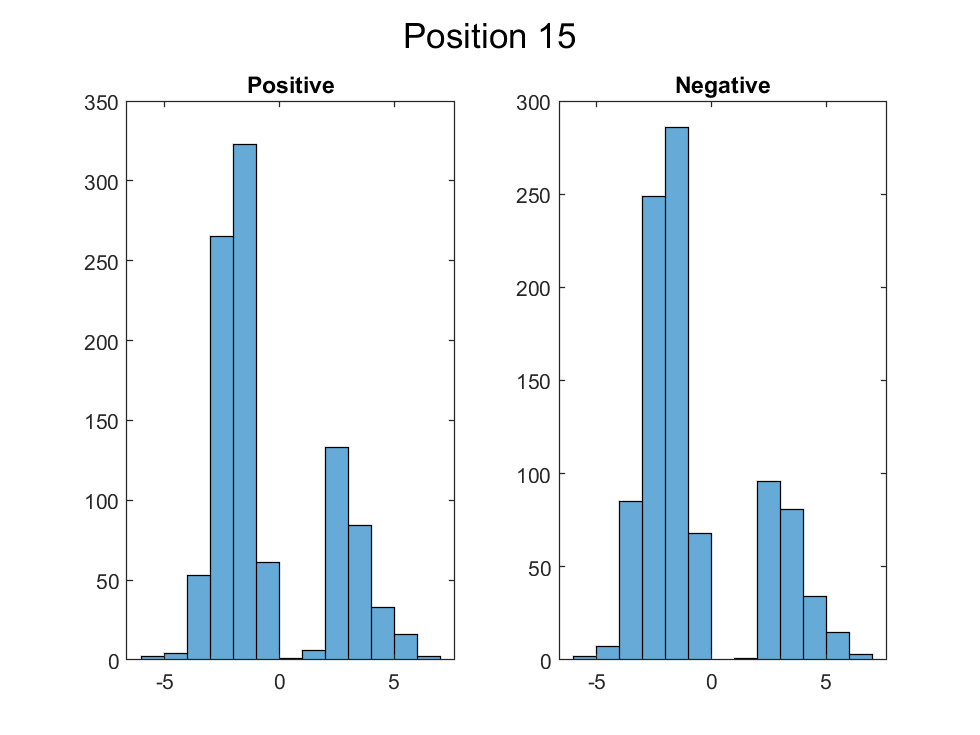

most_common_positive = -1.5000

mean_positive = -1.0780

std_positive = 2.2232

most_common_negative = -1.5000

mean_negative = -1.1898

std_negative = 2.2472

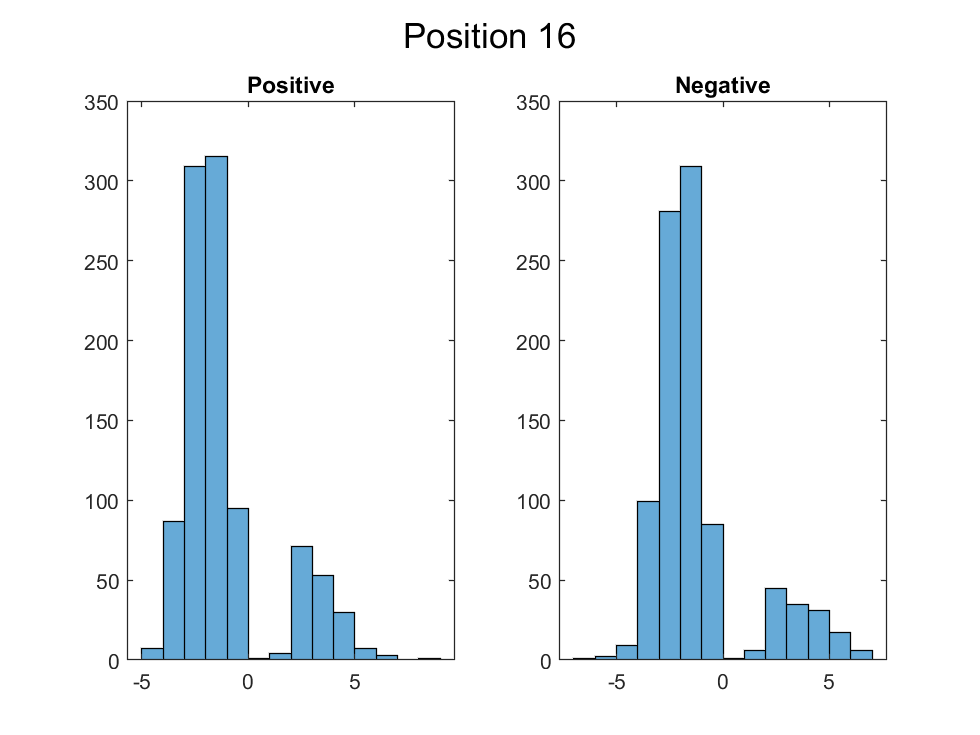

most_common_positive = -2.5000

mean_positive = -0.3634

std_positive = 2.6638

most_common_negative = -2.5000

mean_negative = -0.6025

std_negative = 2.6699

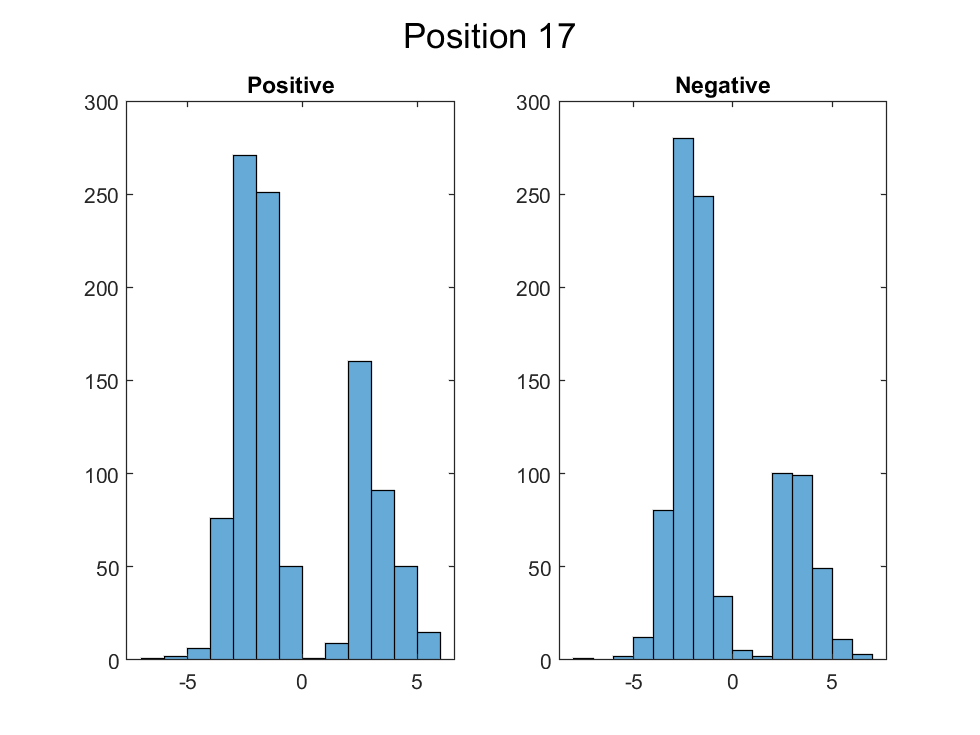

most_common_positive = -1.5000

mean_positive = -0.5322

std_positive = 2.4707

most_common_negative = -2.5000

mean_negative = -0.5694

std_negative = 2.6208

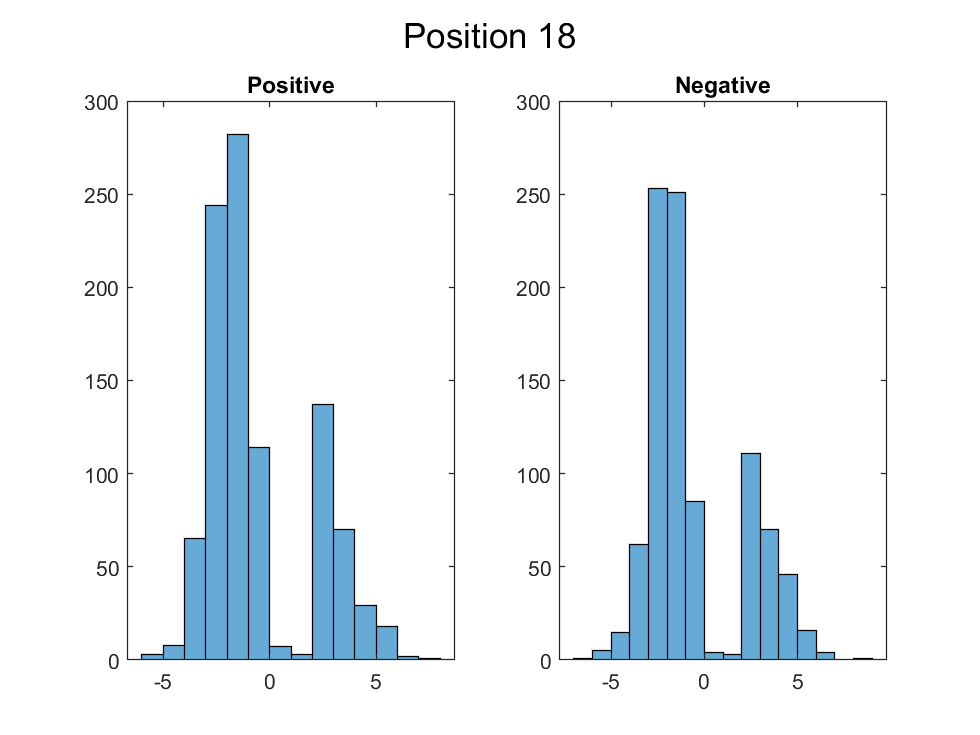

most_common_positive = -1.5000

mean_positive = -1.0476

std_positive = 2.3591

most_common_negative = -1.5000

mean_negative = -0.9733

std_negative = 2.4332

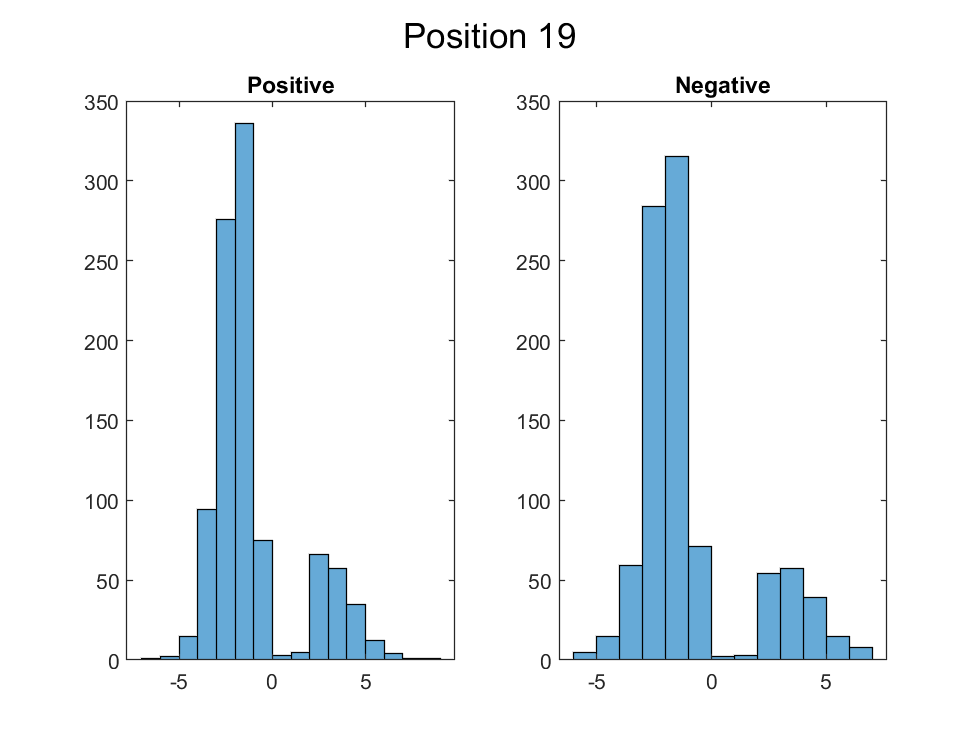

most_common_positive = -2.5000

mean_positive = -0.6562

std_positive = 2.6562

most_common_negative = -1.5000

mean_negative = -0.7626

std_negative = 2.5718

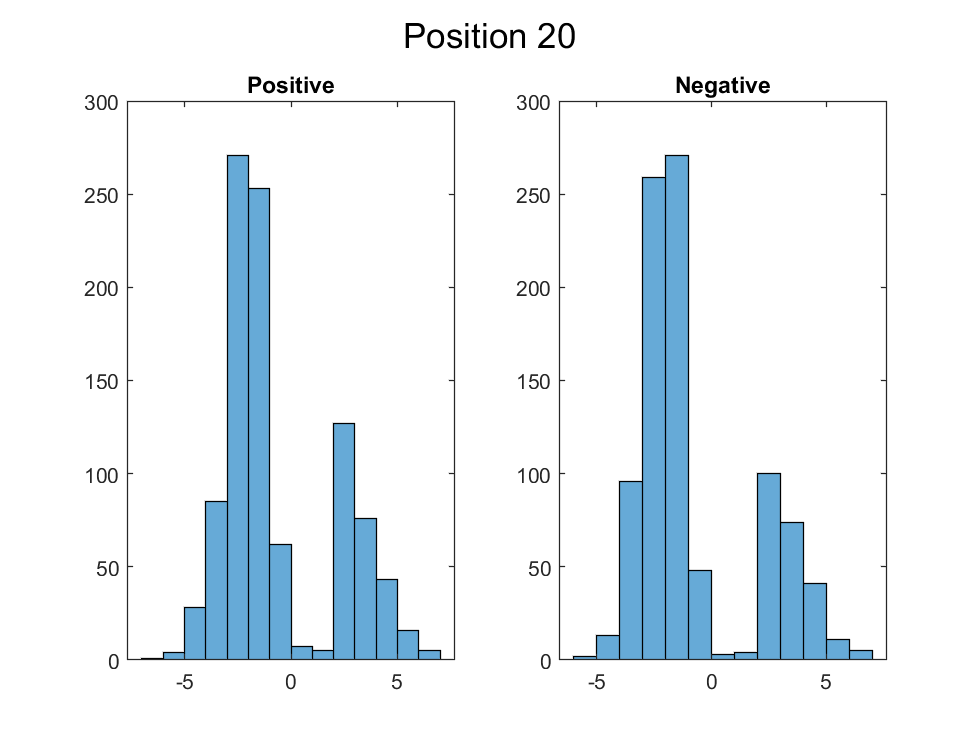

most_common_positive = -1.5000

mean_positive = -1.0971

std_positive = 2.4924

most_common_negative = -1.5000

mean_negative = -0.9716

std_negative = 2.5103

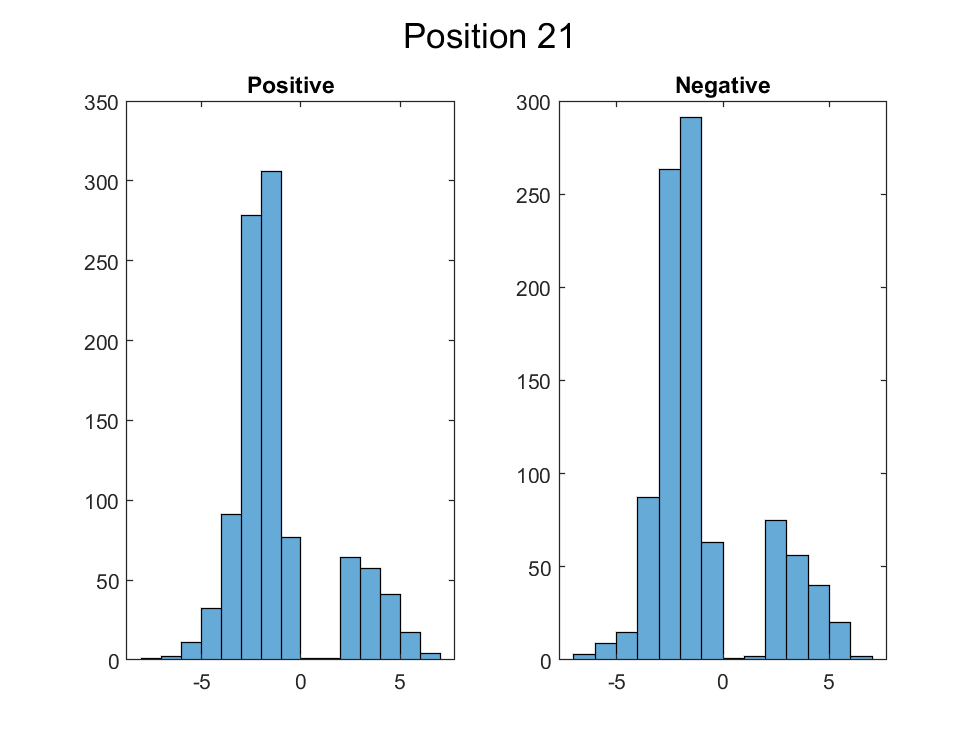

most_common_positive = -1.5000

mean_positive = -1.1892

std_positive = 2.5315

most_common_negative = -1.5000

mean_negative = -1.1959

std_negative = 2.4073

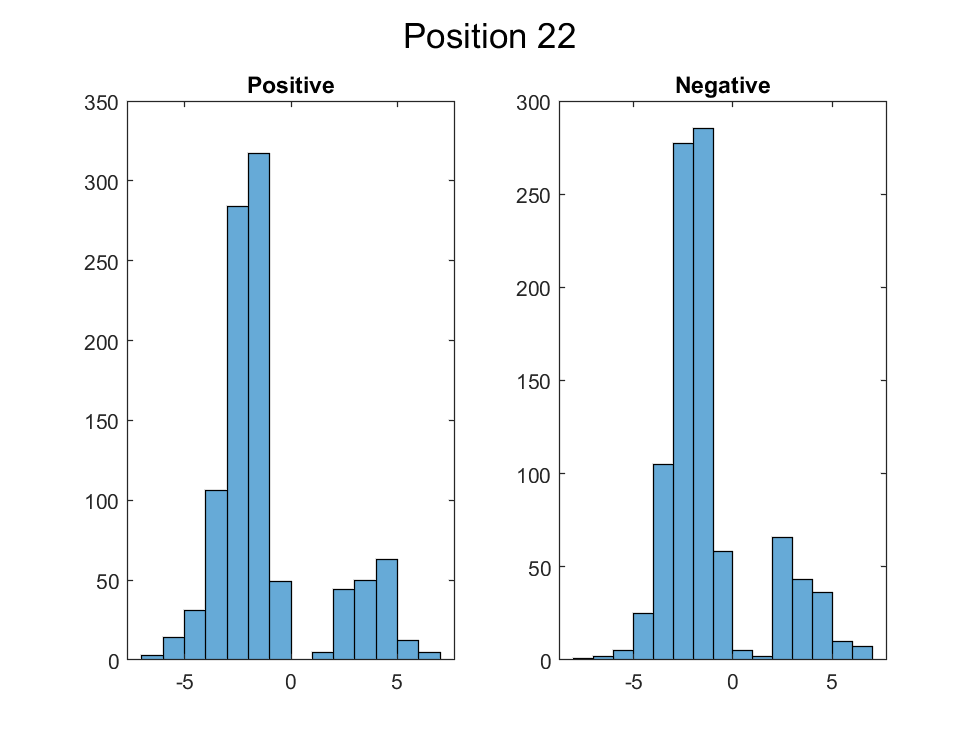

for i=1:22
    positive_col = x_data_positive(:, i);
    
    figure;
    subplot(1, 2, 1)
    h_positive = histogram(positive_col);
    [~, idx] = max(h_positive.Values);
    most_common_positive = h_positive.BinEdges(idx) + (h_positive.BinWidth / 2)
    mean_positive = mean(positive_col)
    std_positive = std(positive_col)
    title("Positive")
    
    negative_col = x_data_negative(:, i);
    subplot(1, 2, 2)
    h_negative = histogram(negative_col);
    [~, idx] = max(h_negative.Values);
    most_common_negative = h_negative.BinEdges(idx) + (h_negative.BinWidth / 2)
    mean_negative = mean(negative_col)
    std_negative = std(negative_col)
    title("Negative")
    
    sgtitle(strcat("Position ", string(i)))
end